# Two Pendulum Cart 

By Rohit Reddy Pakhala (rpakhala-119399125) & Sai Teja  

## C. Conditions for controlability

clear;
clc;
close all;


## defining the variables

syms m1 m2 M g l1 l2 F
%m1, m2 are masses and l1, l2 are lengths respectively
A = [0 1 0 0 0 0; 
    0 0 -m1*g/M 0 -m2*g/M 0; 0 0 0 1 0 0; 
    0 0 -((M*g)+(m1*g))/(M*l1) 0 -g*m2/(M*l1) 0; 
    0 0 0 0 0 1;
    0 0 -m1*g/(M*l2) 0 -((M*g)+(m2*g))/(M*l2) 0];
disp(A)

$$\left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{g\,m_{1}}{M} & 0 & -\frac{g\,m_{2}}{M} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{M\,g+g\,m_{1}}{M\,l_{1}} & 0 & -\frac{g\,m_{2}}{M\,l_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{g\,m_{1}}{M\,l_{2}} & 0 & -\frac{M\,g+g\,m_{2}}{M\,l_{2}} & 0 \end{array}\right)$$

B = [0;1/M;0;1/(l1*M);0;1/(l2*M)];
disp(B)

$$\left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ \frac{1}{M\,l_{1}}\\ 0\\ \frac{1}{M\,l_{2}} \end{array}\right)$$

%cotrolability matrix is given by
Ct = [B A*B (A^2)*B (A^3)*B (A^4)*B (A^5)*B]

$$Ct = \begin{array}{l} \left(\begin{array}{cccccc} 0 & \frac{1}{M} & 0 & \sigma_{1} & 0 & \sigma_{4}\\ \frac{1}{M} & 0 & \sigma_{1} & 0 & \sigma_{4} & 0\\ 0 & \frac{1}{M\,l_{1}} & 0 & \sigma_{6} & 0 & \sigma_{3}\\ \frac{1}{M\,l_{1}} & 0 & \sigma_{6} & 0 & \sigma_{3} & 0\\ 0 & \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{2}\\ \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{g\,m_{1}}{M^{2}\,l_{1}}-\frac{g\,m_{2}}{M^{2}\,l_{2}}\\ \sigma_{2}=\frac{\frac{{\sigma_{7}}^{2}}{M^{2}\,{l_{2}}^{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{\sigma_{8}}}{M\,l_{2}}+\frac{\frac{g\,m_{1}\,\sigma_{7}}{M^{2}\,{l_{2}}^{2}}+\frac{g\,m_{1}\,\sigma_{9}}{\sigma_{8}}}{M\,l_{1}}\\ \sigma_{3}=\frac{\frac{{\sigma_{9}}^{2}}{M^{2}\,{l_{1}}^{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{\sigma_{8}}}{M\,l_{1}}+\frac{\frac{g\,m_{2}\,\sigma_{9}}{M^{2}\,{l_{1}}^{2}}+\frac{g\,m_{2}\,\sigma_{7}}{\sigma_{8}}}{M\,l_{2}}\\ \sigma_{4}=\frac{\frac{g\,m_{1}\,\sigma_{9}}{M^{2}\,l_{1}}+\frac{g^{2}\,m_{1}\,m_{2}}{M^{2}\,l_{2}}}{M\,l_{1}}+\frac{\frac{g\,m_{2}\,\sigma_{7}}{M^{2}\,l_{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{M^{2}\,l_{1}}}{M\,l_{2}}\\ \sigma_{5}=-\frac{\sigma_{7}}{M^{2}\,{l_{2}}^{2}}-\frac{g\,m_{1}}{\sigma_{8}}\\ \sigma_{6}=-\frac{\sigma_{9}}{M^{2}\,{l_{1}}^{2}}-\frac{g\,m_{2}}{\sigma_{8}}\\ \sigma_{7}=M\,g+g\,m_{2}\\ \sigma_{8}=M^{2}\,l_{1}\,l_{2}\\ \sigma_{9}=M\,g+g\,m_{1} \end{array}$$

Rank = rank(Ct)

Rank = 6

Detetminant = det(Ct)

$$Detetminant = -\frac{g^{6}\,{l_{1}}^{2}-2\,g^{6}\,l_{1}\,l_{2}+g^{6}\,{l_{2}}^{2}}{M^{6}\,{l_{1}}^{6}\,{l_{2}}^{6}}$$

cc=simplify(det(Ct))

$$cc = -\frac{g^{6}\,{\left(l_{1}-l_{2}\right)}^{2}}{M^{6}\,{l_{1}}^{6}\,{l_{2}}^{6}}$$

length(A)

ans = 6

ct = Rank - length(A)

ct = 0

%As the result is zero the system is not controllable / Uncontrollable
%So getting a condition for controlability
Ct1 = subs(Ct,l1,l2) %substituting l1=l2

$$Ct1 = \begin{array}{l} \left(\begin{array}{cccccc} 0 & \frac{1}{M} & 0 & \sigma_{1} & 0 & \sigma_{4}\\ \frac{1}{M} & 0 & \sigma_{1} & 0 & \sigma_{4} & 0\\ 0 & \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{2}\\ \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{2} & 0\\ 0 & \frac{1}{M\,l_{2}} & 0 & \sigma_{6} & 0 & \sigma_{3}\\ \frac{1}{M\,l_{2}} & 0 & \sigma_{6} & 0 & \sigma_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{g\,m_{1}}{M^{2}\,l_{2}}-\frac{g\,m_{2}}{M^{2}\,l_{2}}\\ \sigma_{2}=\frac{\frac{{\sigma_{9}}^{2}}{\sigma_{11}}+\sigma_{7}}{M\,l_{2}}+\frac{\frac{g\,m_{2}\,\sigma_{9}}{\sigma_{11}}+\frac{g\,m_{2}\,\sigma_{10}}{\sigma_{11}}}{M\,l_{2}}\\ \sigma_{3}=\frac{\frac{{\sigma_{10}}^{2}}{\sigma_{11}}+\sigma_{7}}{M\,l_{2}}+\frac{\frac{g\,m_{1}\,\sigma_{9}}{\sigma_{11}}+\frac{g\,m_{1}\,\sigma_{10}}{\sigma_{11}}}{M\,l_{2}}\\ \sigma_{4}=\frac{\frac{g\,m_{1}\,\sigma_{9}}{M^{2}\,l_{2}}+\sigma_{8}}{M\,l_{2}}+\frac{\frac{g\,m_{2}\,\sigma_{10}}{M^{2}\,l_{2}}+\sigma_{8}}{M\,l_{2}}\\ \sigma_{5}=-\frac{\sigma_{9}}{\sigma_{11}}-\frac{g\,m_{2}}{\sigma_{11}}\\ \sigma_{6}=-\frac{\sigma_{10}}{\sigma_{11}}-\frac{g\,m_{1}}{\sigma_{11}}\\ \sigma_{7}=\frac{g^{2}\,m_{1}\,m_{2}}{\sigma_{11}}\\ \sigma_{8}=\frac{g^{2}\,m_{1}\,m_{2}}{M^{2}\,l_{2}}\\ \sigma_{9}=M\,g+g\,m_{1}\\ \sigma_{10}=M\,g+g\,m_{2}\\ \sigma_{11}=M^{2}\,{l_{2}}^{2} \end{array}$$

det1 = det(Ct1)

$$det1 = 0$$

rank(Ct1)

ans = 4

disp('the system is uncontrollable when l1=l2 as det is zero')

the system is uncontrollable when l1=l2 as det is zero


disp('the system is controllable when l1 != l2, l1 !=0, and l2 !=0 ')

the system is controllable when l1 != l2, l1 !=0, and l2 !=0 


## D. LQR Controller

As = double(subs(A, {g, l1, l2, m1, m2, M}, {9.8, 20, 10, 100, 100, 1000}))

As =          0    1.0000         0         0         0         0
         0         0   -0.9800         0   -0.9800         0
         0         0         0    1.0000         0         0
         0         0   -0.5390         0   -0.0490         0
         0         0         0         0         0    1.0000
         0         0   -0.0980         0   -1.0780         0


Bs = double(subs(B, {g, l1, l2, m1, m2, M}, {9.8, 20, 10, 100, 100, 1000}))

Bs = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


cont = ctrb(As,Bs)

cont = 1.0e-03 *

         0    1.0000         0   -0.1470         0    0.1417
    1.0000         0   -0.1470         0    0.1417         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1127         0    0.1246
    0.1000         0   -0.1127         0    0.1246         0


if (rank(cont)==6)
    disp("Rank of cont is quals to A Hence the system is controllable")
else
    disp("Rank of cont is not equal to A, system is uncontrollable")
end

Rank of cont is quals to A Hence the system is controllable


% Assumin the Q matrix
Q =[5 0 0 0 0 0;
    0 0 0 0 0 0 ;
    0 0 5000 0 0 0;
    0 0 0 0 0 0 ;
    0 0 0 0 5000 0;
    0 0 0 0 0 0]

Q =            5           0           0           0           0           0
           0           0           0           0           0           0
           0           0        5000           0           0           0
           0           0           0           0           0           0
           0           0           0           0        5000           0
           0           0           0           0           0           0


R=0.01

R = 0.0100

C = eye(6)

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D = 0;
%initial state is given below
initial_state = [0;0;20;0;10;0]

initial_state =      0
     0
    20
     0
    10
     0


%ss is the MATLAB function to find the state space representation of the
%system
sys_1 = ss(As, Bs, C, D)

sys_1 =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       1       0       0       0       0
   x2       0       0   -0.98       0   -0.98       0
   x3       0       0       0       1       0       0
   x4       0       0  -0.539       0  -0.049       0
   x5       0       0       0       0       0       1
   x6       0       0  -0.098       0  -1.078       0
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
 
Continuous-time state-space model.



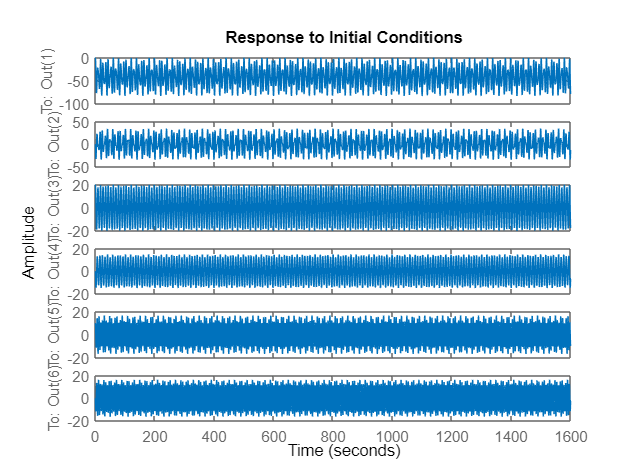

figure
initial(sys_1,initial_state)

%lqr is in-buit LQR controller function
[K_matrix_gain, S_matrix, P] = lqr(As, Bs, Q, R);
K_matrix_gain, S_matrix, P

K_matrix_gain =    22.3607  234.6518  131.1793  678.6548  174.6940  360.1045


S_matrix = 1.0e+05 *

    0.0005    0.0028    0.0015   -0.0051    0.0008   -0.0026
    0.0028    0.0287    0.0210   -0.0501    0.0111   -0.0268
    0.0015    0.0210    1.3083    0.0230    0.0017   -0.0903
   -0.0051   -0.0501    0.0230    2.5161    0.1147   -0.0783
    0.0008    0.0111    0.0017    0.1147    0.6957    0.0065
   -0.0026   -0.0268   -0.0903   -0.0783    0.0065    0.6675


P =   -0.0197 + 0.7282i
  -0.0197 - 0.7282i
  -0.0364 + 1.0432i
  -0.0364 - 1.0432i
  -0.0961 + 0.0966i
  -0.0961 - 0.0966i


%eigen values
eig(S_matrix)

ans = 1.0e+05 *

    0.0003
    0.0261
    0.6502
    0.6918
    1.3204
    2.5281


sys_2 = ss(As-(Bs*K_matrix_gain),Bs,C,D)

sys_2 =
 
  A = 
              x1         x2         x3         x4         x5         x6
   x1          0          1          0          0          0          0
   x2   -0.02236    -0.2347     -1.111    -0.6787     -1.155    -0.3601
   x3          0          0          0          1          0          0
   x4  -0.001118   -0.01173    -0.5456   -0.03393   -0.05773   -0.01801
   x5          0          0          0          0          0          1
   x6  -0.002236   -0.02347    -0.1111   -0.06787     -1.095   -0.03601
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
 
Continuous-time state-space model.



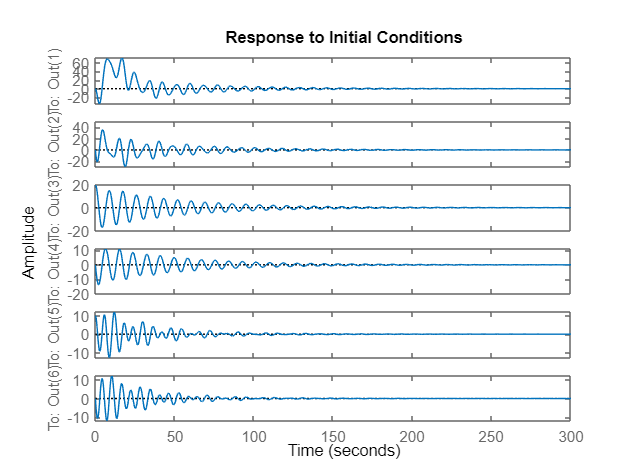

figure
initial(sys_2,initial_state)

## Non-linear

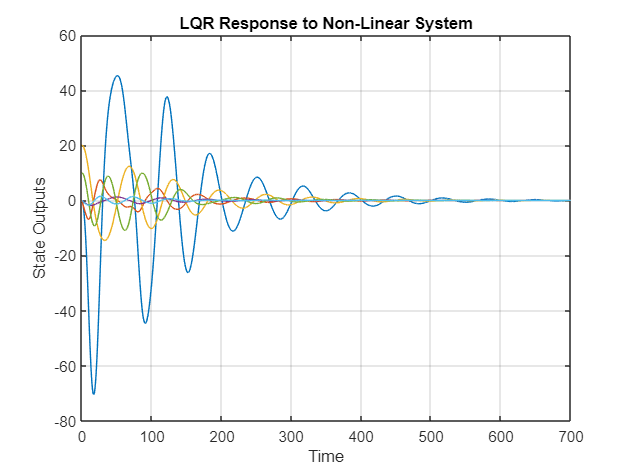

% x, theta_1 and theta_2 values are defined
%"timespan"
    time = 0:0.1:700; 
%ode45 function is used for definining a differential eqn
    [timeperiod,y1] = ode45(@ydot_func,time,initial_state); 
%plotting output of the function as 2D graph
    plot(timeperiod,y1)
    title('LQR Response to Non-Linear System')
    xlabel('Time')
    ylabel('State Outputs')
    grid on

## E. Observability

%Jacobian linearization of the non linear system of dual pendulum suspended on a crane
%From the problem statement, the output vectors are
% x(t), (theta1(t),theta2(t)), (x(t), theta1(t)),and (x(t),theta1(t),theta2(t)) as C1,C2,C3, and C4 respectively
%because Y = CX+DU, we take C matrix values such that it accounts for the
%state variable
C1 =[1 0 0 0 0 0];
%coressponding to theta1 and theta2
C2 =[0 0 1 0 0 0;
     0 0 0 0 1 0];
%corresponding to x and theta2
C3 =[1 0 0 0 0 0;
     0 0 0 0 1 0];
%corresponding to x, theta1, and theta2
C4 =[1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 1 0];
%let observability matrix is defined as O_1, O_2, O_3, and O_4
O_1 = [C1' A'*C1' A'*A'*C1' A'*A'*A'*C1' A'*A'*A'*A'*C1' A'*A'*A'*A'*A'*C1'];
O_2 = [C2' A'*C2' A'*A'*C2' A'*A'*A'*C2' A'*A'*A'*A'*C2' A'*A'*A'*A'*A'*C2'];
O_3 = [C3' A'*C3' A'*A'*C3' A'*A'*A'*C3' A'*A'*A'*A'*C3' A'*A'*A'*A'*A'*C3'];
O_4 = [C4' A'*C4' A'*A'*C4' A'*A'*A'*C4' A'*A'*A'*A'*C4' A'*A'*A'*A'*A'*C4'];
rankArr = [rank(O_1),rank(O_2),rank(O_3),rank(O_4)];
for r = 1:4
    disp("Rank of the observability Matrix: of O_"+r+" is :"+rankArr(r))
    if rankArr(r)==6
        disp('System is observable')
    else 
        disp('System is not observable')
    end
end

Rank of the observability Matrix: of O_1 is :6


System is observable


Rank of the observability Matrix: of O_2 is :4


System is not observable


Rank of the observability Matrix: of O_3 is :6


System is observable


Rank of the observability Matrix: of O_4 is :6


System is observable


## F. Luenberger Observer

%luenberger observer for linearized system
desired_poles = [-1;-3;-2;-4;-6;-8]

desired_poles =     -1
    -3
    -2
    -4
    -6
    -8


%state feedback matrix
k = lqr(As,Bs,Q,R)

k =    22.3607  234.6518  131.1793  678.6548  174.6940  360.1045


% output vectors as per pole placements
L_1 = place(As',C1',desired_poles)';
L_3 = place(As',C3',desired_poles)';
L_4 = place(As',C4',desired_poles)';
Bs_C = [Bs;zeros(size(B))]

Bs_C = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000
         0
         0
         0
         0


% output vector 1
A_C1 = [(As-Bs*k) Bs*k; zeros(size(As)) (As-L_1*C1)];
C_C1 = [C1 zeros(size(C1))];
% ouput vector 3
A_C3 = [(As-Bs*k) Bs*k; zeros(size(As)) (As-L_3*C3)];
C_C3 = [C3 zeros(size(C3))];
%output vector 4
A_C4 = [(As-Bs*k) Bs*k; zeros(size(As)) (As-L_4*C4)];
C_C4 = [C4 zeros(size(C4))];
% intial conditions
initial_state = [1;0;30;2;60;2;zeros(6,1)]

initial_state =      1
     0
    30
     2
    60
     2
     0
     0
     0
     0


sys1 = ss(A_C1, Bs_C, C_C1,D);
sys3 = ss(A_C3, Bs_C, C_C3,D);
sys4 = ss(A_C4, Bs_C, C_C4,D);
disp("Observer error with x(t) output vector")

Observer error with x(t) output vector


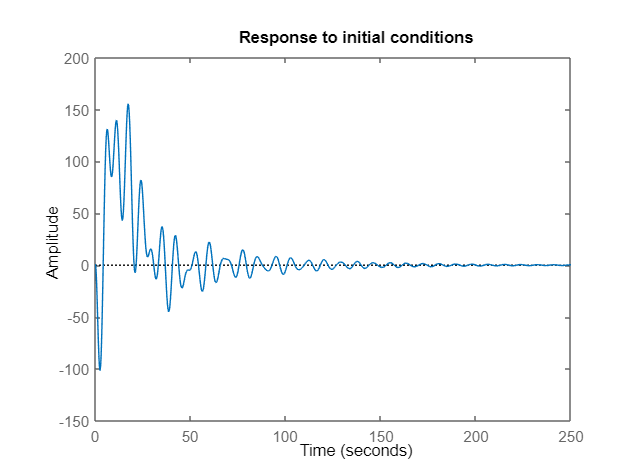

figure
initial(sys1,initial_state)
title("Response to initial conditions");

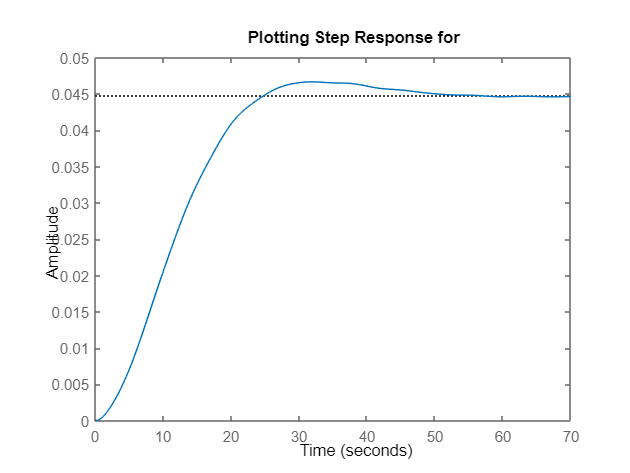

figure
step(sys1)
title("Plotting Step Response for ")


disp("Observer error with x(t), theta2(t)")

Observer error with x(t), theta2(t)


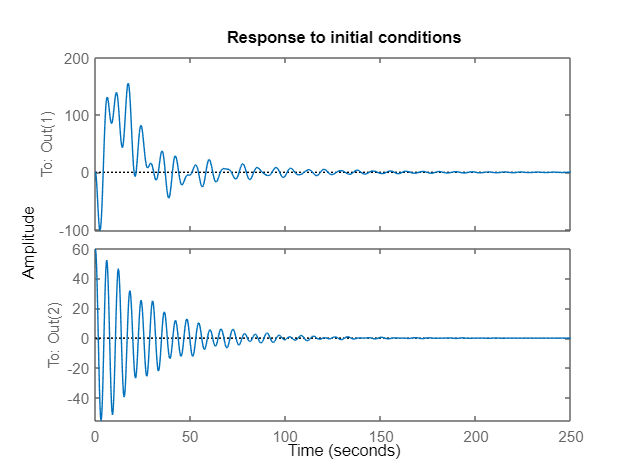

figure
initial(sys3,initial_state)
title("Response to initial conditions")

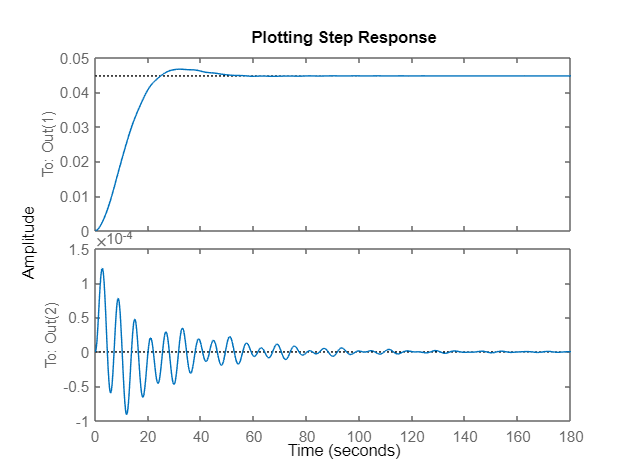

figure
step(sys3)
title("Plotting Step Response")

disp("Observer error with x(t), theta1(t), theta2(t)")

Observer error with x(t), theta1(t), theta2(t)


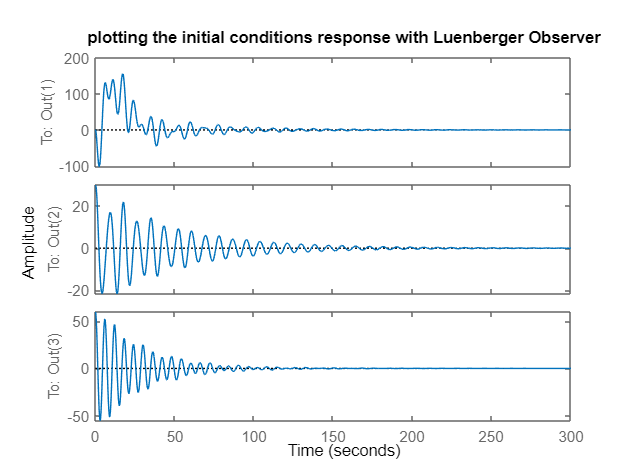

figure
initial(sys4,initial_state)
title("plotting the initial conditions response with Luenberger Observer")

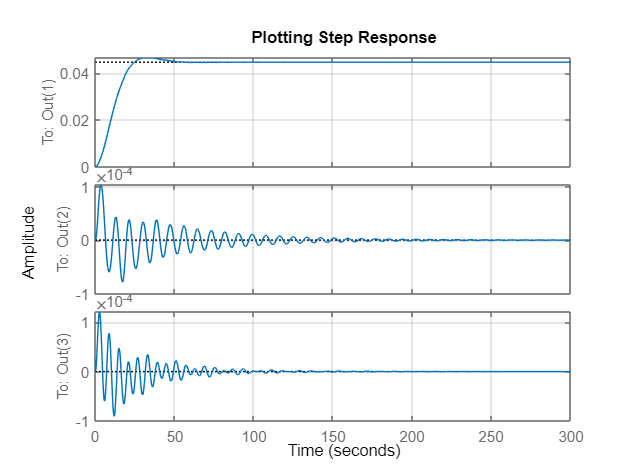

figure
step(sys4)
title("Plotting Step Response")
grid on

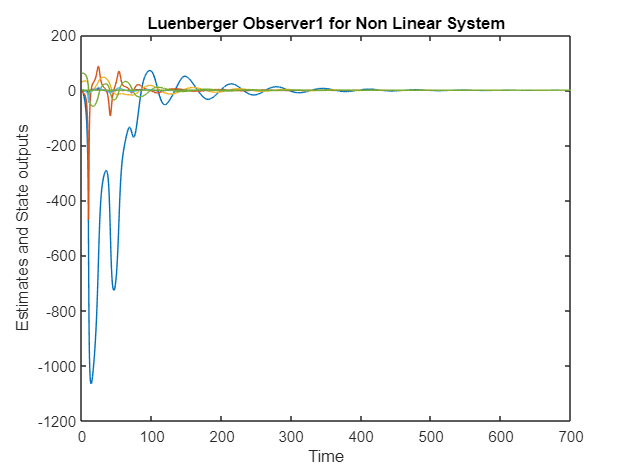

%Luenberger Observer for Non Linear System Model:
%plotting the estimates. Not plotting the error

simulation_time = 0:0.1:700;
[time,out] = ode45(@luenberger_func,simulation_time,initial_state);
figure
plot(time,out)
title('Luenberger Observer1 for Non Linear System')
xlabel('Time')
ylabel('Estimates and State outputs')

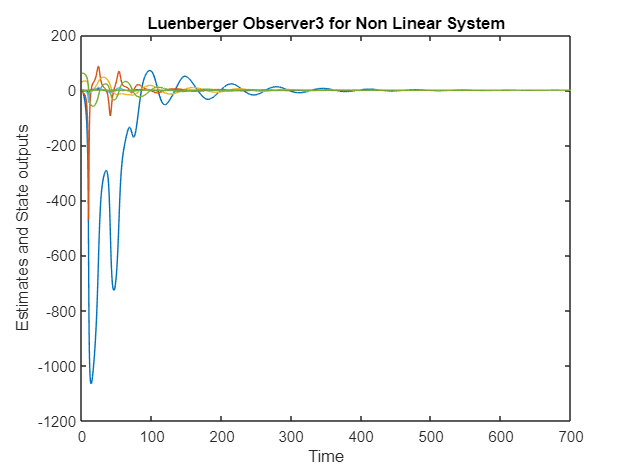

[time,out] = ode45(@luenberger_func3,simulation_time,initial_state);
figure
plot(time,out)
title('Luenberger Observer3 for Non Linear System')
xlabel('Time')
ylabel('Estimates and State outputs')

## G. LQG Controller

QXU = eye(7)

QXU =      1     0     0     0     0     0     0
     0     1     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     1     0     0     0
     0     0     0     0     1     0     0
     0     0     0     0     0     1     0
     0     0     0     0     0     0     1


% process noise
%wgn is in-buit MATLAB to generate gaussian process noise
w = wgn(6,1,4)

w =     0.5430
    5.6714
    4.3893
   -2.1394
    4.8100
    1.1497


% generating measurement noise
v = wgn(1,1,4)

v = -0.0999

QWV = [w;v]*[w' v']

QWV =     0.2949    3.0797    2.3835   -1.1618    2.6120    0.6243   -0.0543
    3.0797   32.1645   24.8932  -12.1335   27.2795    6.5203   -0.5668
    2.3835   24.8932   19.2656   -9.3905   21.1125    5.0463   -0.4386
   -1.1618  -12.1335   -9.3905    4.5771  -10.2907   -2.4597    0.2138
    2.6120   27.2795   21.1125  -10.2907   23.1364    5.5300   -0.4807
    0.6243    6.5203    5.0463   -2.4597    5.5300    1.3218   -0.1149
   -0.0543   -0.5668   -0.4386    0.2138   -0.4807   -0.1149    0.0100


%state space representation of the closed loop system with LQG controller
sys5 = ss(As,Bs,C1,D)

sys5 =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       1       0       0       0       0
   x2       0       0   -0.98       0   -0.98       0
   x3       0       0       0       1       0       0
   x4       0       0  -0.539       0  -0.049       0
   x5       0       0       0       0       0       1
   x6       0       0  -0.098       0  -1.078       0
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys_LQG = lqg(sys5,QXU,QWV);
initial_state_2 = [1;2;30;3;30;3]

initial_state_2 =      1
     2
    30
     3
    30
     3


figure
disp("Response at initial conditions")

Response at initial conditions


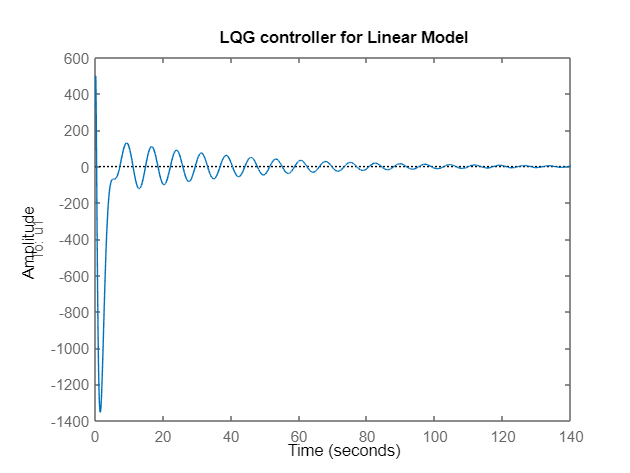

figure
initial(sys_LQG,initial_state_2)
title("LQG controller for Linear Model")

disp("Response at step LQR control")

Response at step LQR control


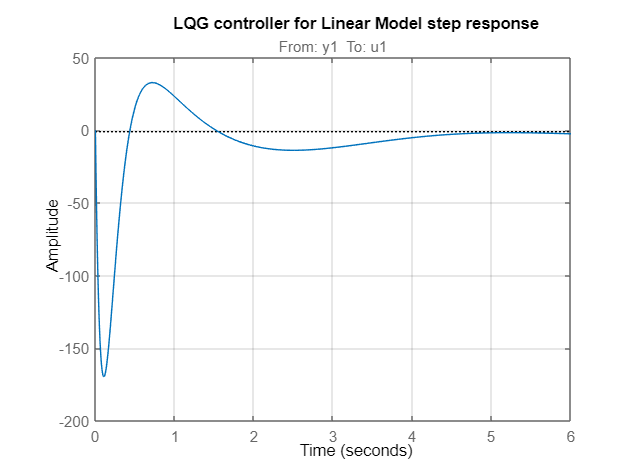

figure
step(sys_LQG)
title("LQG controller for Linear Model step response")
grid on

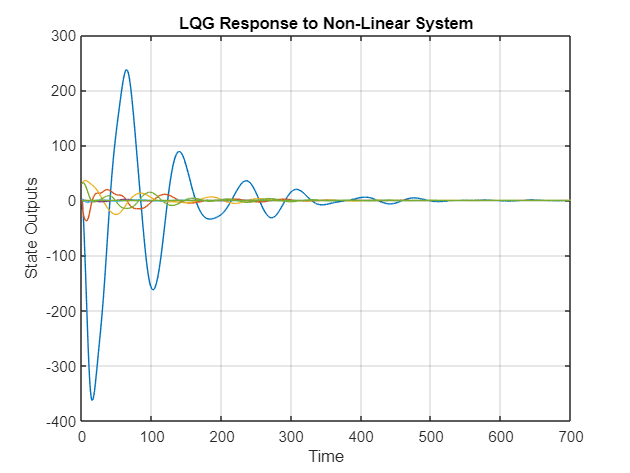

time_samples = 0:0.1:700;
initial_state_Lqg = [1;2;30;3;30;3;zeros(6,1)];
[t2,y] = ode45(@lqg_func,time_samples,initial_state_Lqg);
%plotting output of the function as 2D graph
plot(time_samples,y)
title('LQG Response to Non-Linear System')
xlabel('Time')
ylabel('State Outputs')
grid on